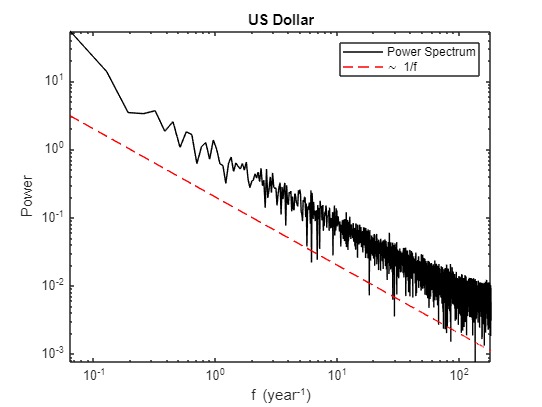

a=importdata("Data.csv",",",1);
usd=a.data(:,1);
pnd=a.data(:,2);
eur=a.data(:,3);
yen=a.data(:,4);
L=length(usd);
fs = (1:(L/2+1))/L*365.;

f_yen=fft(usd);
P2_yen = abs(f_yen/L);
P1_yen = P2_yen(1:floor(L/2+1));
P1_yen(2:end-1) = 2*P1_yen(2:end-1);

loglog(fs,P1_yen,'k')
hold on
loglog(fs,0.2./fs.^1, '--r')
xlabel("f (year^{-1})")
ylabel("Power")
title("US Dollar")
xlim([min(fs) max(fs)])
ylim([min(P1_yen) max(P1_yen)])
legend('Power Spectrum','\sim 1/f')
hold off

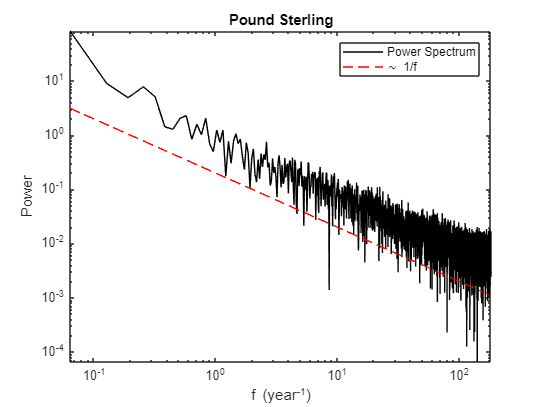

%hold on;

f_yen=fft(pnd);
P2_yen = abs(f_yen/L);
P1_yen = P2_yen(1:floor(L/2+1));
P1_yen(2:end-1) = 2*P1_yen(2:end-1);

loglog(fs,P1_yen,'k')
hold on
loglog(fs,0.2./fs.^1, '--r')
xlabel("f (year^{-1})")
ylabel("Power")
title("Pound Sterling")
xlim([min(fs) max(fs)])
ylim([min(P1_yen) max(P1_yen)])
legend('Power Spectrum','\sim 1/f')
hold off

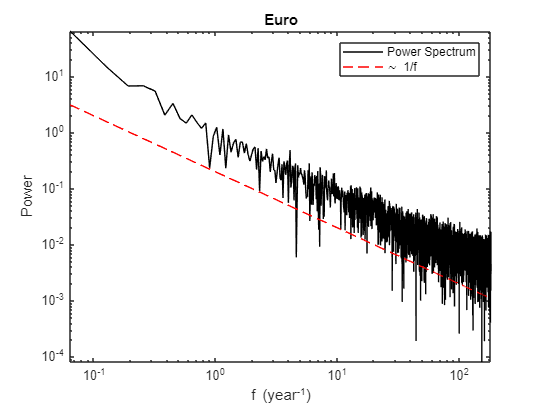

%
% hold on;

f_yen=fft(eur);
P2_yen = abs(f_yen/L);
P1_yen = P2_yen(1:floor(L/2+1));
P1_yen(2:end-1) = 2*P1_yen(2:end-1);

loglog(fs,P1_yen,'k')
hold on
loglog(fs,0.2./fs.^1, '--r')
xlabel("f (year^{-1})")
ylabel("Power")
title("Euro")
xlim([min(fs) max(fs)])
ylim([min(P1_yen) max(P1_yen)])
legend('Power Spectrum','\sim 1/f')
hold off

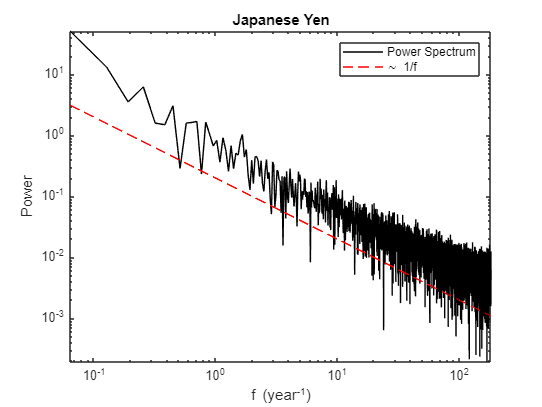


%hold on;

f_yen=fft(yen);
P2_yen = abs(f_yen/L);
P1_yen = P2_yen(1:floor(L/2+1));
P1_yen(2:end-1) = 2*P1_yen(2:end-1);

loglog(fs,P1_yen,'k')
hold on
loglog(fs,0.2./fs.^1, '--r')
xlabel("f (year^{-1})")
ylabel("Power")
title("Japanese Yen")
xlim([min(fs) max(fs)])
ylim([min(P1_yen) max(P1_yen)])
legend('Power Spectrum','\sim 1/f')
hold off

%hold off;

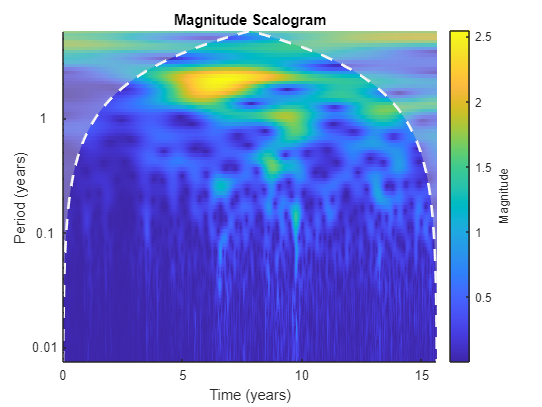

figure()
cwt(usd,'amor',years(1/365.));

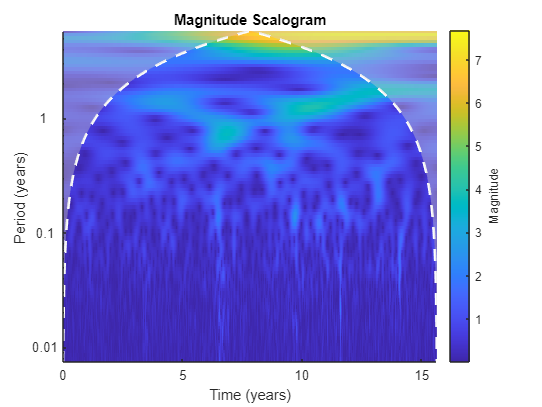

figure()
cwt(pnd,'amor',years(1/365.));

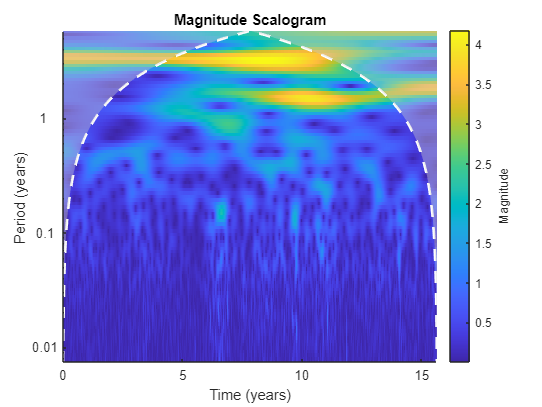


figure()
cwt(eur,'amor',years(1/365.));

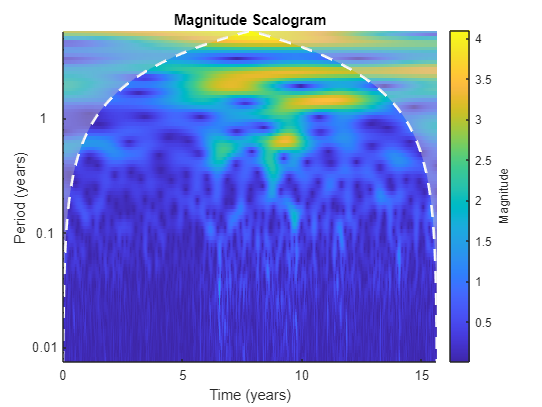


figure()
cwt(yen,'amor',years(1/365.));

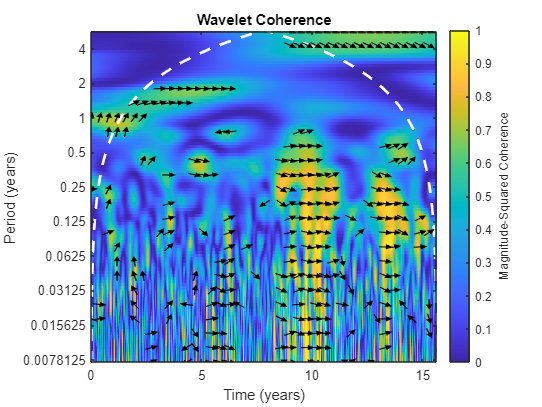

figure()
wcoherence(usd,eur,years(1/365.));

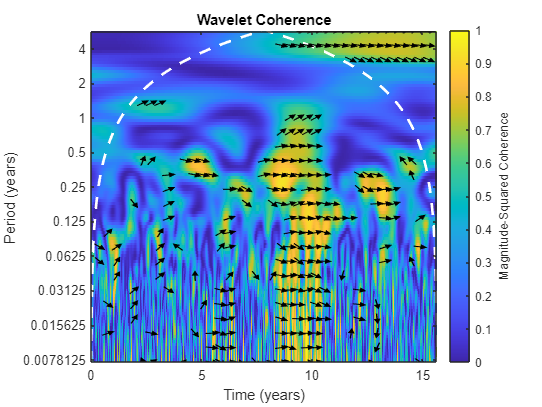

figure()
wcoherence(usd,pnd,years(1/365.));

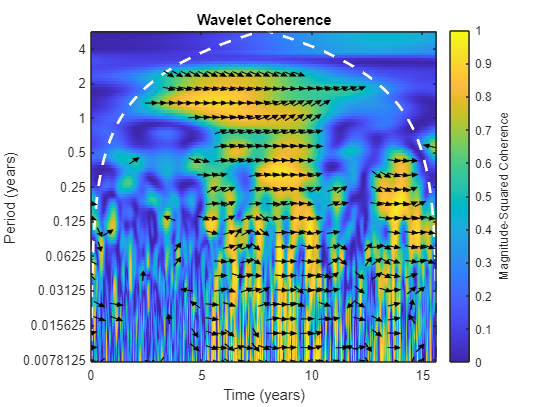

figure()
wcoherence(usd,yen,years(1/365.));

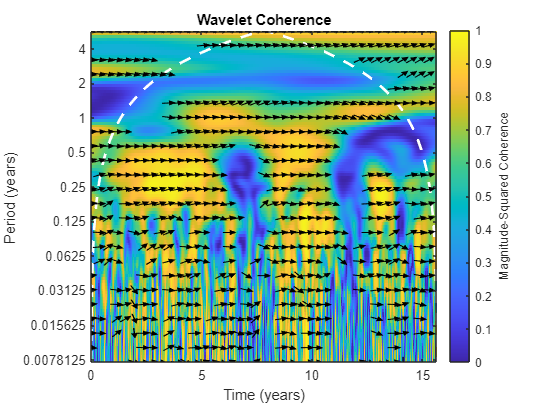

figure()
wcoherence(eur,pnd,years(1/365.));

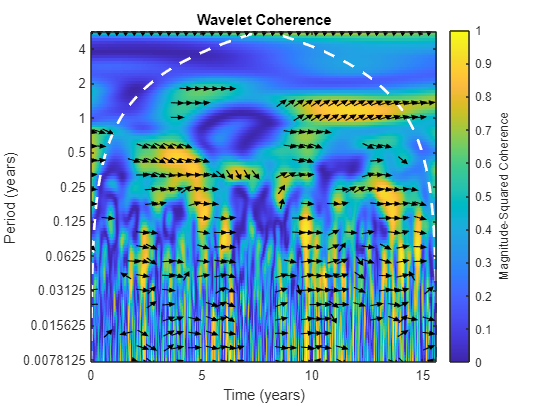

figure()
wcoherence(eur,yen,years(1/365.));

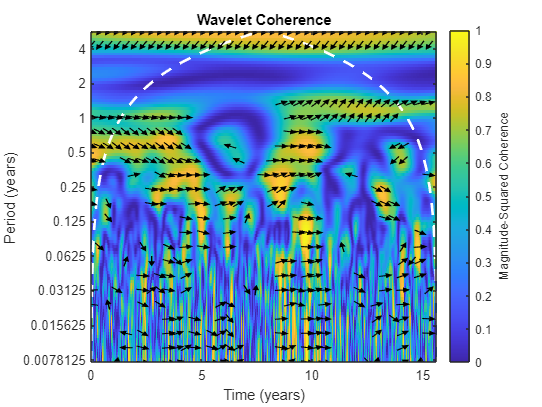


figure()
wcoherence(pnd,yen,years(1/365.));